# Visualize Field

This script provides a step-by-step exploration of the electrostatic dipole, guiding you through its physical principles, numerical modeling, and effective visualization techniques to deepen your understanding of electric fields.

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

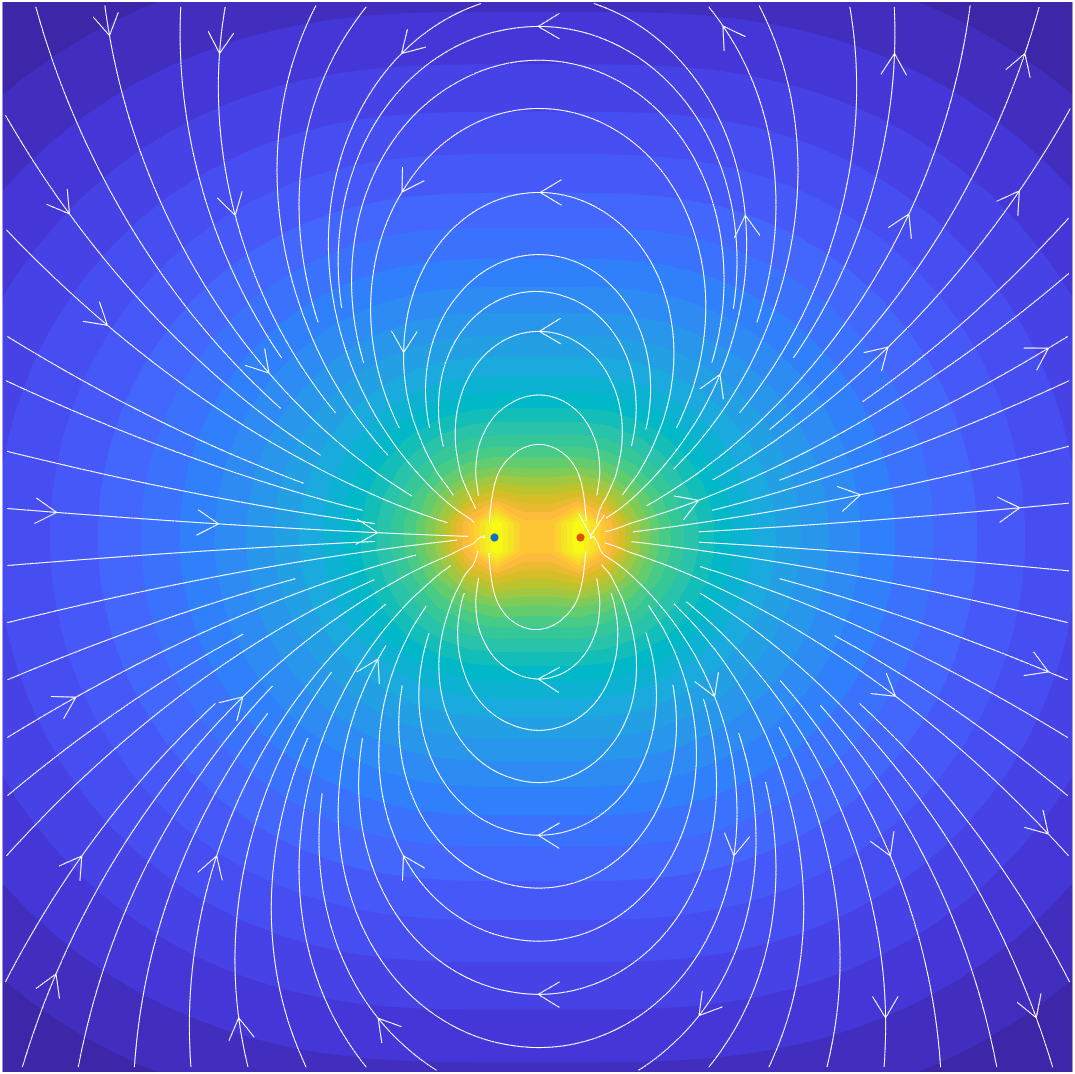

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and they will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## **Problem definition**

The electrostatic dipole problem involves analyzing the electric field and potential generated by two equal and opposite point charges separated by a small distance. Understanding the behavior of such a dipole is fundamental in electrostatics, as it provides insight into the interactions of molecules and the distribution of electric fields in various physical systems.

  **Try.** Visualize the dipole.

d = 0.8;

figure
scatter(-d/2,0,15,'filled',SeriesIndex=1,DisplayName="Negative Charge")
hold on
scatter(d/2,0,15,'filled',SeriesIndex=2,DisplayName="Positive Charge")
hold off
legend(Location="bestoutside")
axis equal
xlim([-5 5])

The first step in numerically solving the electrostatic dipole problem is to discretize the continuous space onto a mesh grid. By dividing the region of interest into a finite set of points, we can approximate the electric potential and field values at each grid point, making the problem suitable for computational analysis.

  **Try.** Define grid.

xLimit = [-5 5];
xNumPoint = 40;
yLimit = [-5 5];
yNumPoint = 40;

xPoint = linspace(xLimit(1),xLimit(2),xNumPoint);
yPoint = linspace(yLimit(1),yLimit(2),yNumPoint);

[xGrid, yGrid] = meshgrid(xPoint,yPoint);

figure
scatter(-d/2,0,15,'filled',SeriesIndex=1,DisplayName="Negative Charge")
hold on
scatter(d/2,0,15,'filled',SeriesIndex=2,DisplayName="Positive Charge")
mesh(xGrid,yGrid,0*yGrid,FaceAlpha=0,DisplayName="Grid")
hold off
legend(Location="bestoutside")
axis equal
xlim([-5 5])

## Compute the field from one of the charge

With the space discretized onto a mesh grid, we can now compute the value of the electric field at each grid point. This allows us to analyze how the field varies throughout the region and to visualize the characteristic pattern produced by the dipole.

    
$$ \vec{E} = k_e \frac{q}{r^2}{\hat{r}}$$
 

  **Try.** Compute the field generated by the positive charge.

% Define the problem parameters
Charge = 1e-3; % 1 mC
k_e = 8.99e9; % Coulomb's constant in N*m^2/C^2

% Compute the r vector
rx = xGrid - d/2; % x-component of r-vector
ry = yGrid; % y-component of the r-vector
r = sqrt(rx.^2 + ry.^2); % r-vector magnitude

% Compute the electric field
Ex = k_e * Charge* rx ./ r.^3; % x-component of electric field
Ey = k_e * Charge* ry ./ r.^3; % y-component of electric field
E = sqrt(Ex.^2 + Ey.^2);

% Plot the field
figure
contourf(xGrid,yGrid,log10(E),15,LineStyle="none",DisplayName="E field magnitude")
hold on
scatter(d/2,0,15,'filled',SeriesIndex=2,DisplayName="Positive Charge")
hold off
legend(Location="bestoutside")
axis equal
xlim([-5 5])

 **Pro-tip. **To make the visualization more straightforward, we plot the logarithm of the magnitude of the electric field; otherwise, due to the $\(1/r^2\)$ dependence of the field, the large variation in values would make it challenging to observe the overall structure.

## **Extend to the second charge**

We can now include the contribution from the second charge, allowing us to compute and visualize the combined electric field produced by the complete dipole configuration.

 **Exercise.** This time, you are the one coding the electric field computation. Complete/Modify the second block of code to account for the field generated by the negative charge.

% Define problem parameters
Charge = 1e-3; % 1 mC
k_e = 8.99e9; % Coulomb's constant in N*m^2/C^2

% 1. Compute field from positive charge
rx = xGrid - d/2;
ry = yGrid;
r = sqrt(rx.^2 + ry.^2);
Ex = k_e * Charge* rx ./ r.^3; % x-component of electric field
Ey = k_e * Charge* ry ./ r.^3; % y-component of electric field

% 2. Compute field from negative charge
rx = ;
ry = ;
r = sqrt(rx.^2 + ry.^2);
Ex = Ex + ; % x-component of electric field
Ey = Ey + ; % y-component of electric field

% 3. Compute magnitude of total field.
E = sqrt(Ex.^2 + Ey.^2);

figure
contourf(xGrid,yGrid,log10(E),15,LineStyle="none")
hold on
scatter(-d/2,0,15,'filled',SeriesIndex=1,DisplayName="Negative Charge")
scatter(d/2,0,15,'filled',SeriesIndex=2,DisplayName="Positive Charge")
hold off
legend(Location="bestoutside")
axis equal
xlim([-5 5])

## **Further Exploration**

The contour plot visualizes only the magnitude of the electric field without conveying any information about its direction. To gain insight into the field's orientation and flow, you may use field line visualizations, which illustrate the electric field's strength and direction throughout the region.

  **Try. **Visualized the electric field lines.

figure
streamslice(xGrid,yGrid,Ex,Ey)
hold on
scatter(-d/2,0,15,'filled',SeriesIndex=1,DisplayName="Negative Charge")
scatter(d/2,0,15,'filled',SeriesIndex=2,DisplayName="Positive Charge")
hold off
axis equal
xlim([-5 5])

You can even overlay both the contour plot and the field lines in a single visualization to display the magnitude and direction of the electric field simultaneously. This combined approach offers a more complete and intuitive understanding of the dipole's behavior.

  **Try. **Using `hold`, we can even superpose the field lines over the contour plot.

figure
contourf(xGrid,yGrid,log10(E),30,LineStyle="none")
hold on
lines = streamslice(xGrid,yGrid,Ex,Ey);
set(lines,"Color","w")
scatter(-d/2,0,15,'filled',SeriesIndex=1,DisplayName="Negative Charge")
scatter(d/2,0,15,'filled',SeriesIndex=2,DisplayName="Positive Charge")
hold off
axis equal

 **Reflect**. The final figure in this script should be similar to the script cover picture. If you are stuck or cannot find this image, check out the solutions [here](matlab:open('..\InstructorResources\Solutions\VisualizeFieldSoln.mlx')).

## Conclusion

In summary, by discretizing space, calculating the electric field, and employing various visualization techniques, we have gained valuable insights into the behavior of the electrostatic dipole. These methods enhance our understanding of fundamental electrostatics and provide essential tools for analyzing more complex charge distributions in physics and engineering.

[⇦ Main Menu](matlab:open('MainMenu.mlx'))